# PNNL Chemometric Methods

Copyright 2022 Battelle Memorial Institute

## Classical Least Squares (CLS)

Classical least squares computes $C_\textrm{cls}$ that minimizes $||CK_\textrm{cls}-A_\textrm{unkown}||_2$, where $CK=A$ is the Beer's law relationship between concentration $C$, extinction coefficient $K$, and absorbtion $A$.  Multiplier matrix $B_\textrm{cls}$ is the pseudo-inverse of Beer's law extinction coefficient matrix $K_\textrm{cls}$ such that $C_\textrm{cls} = A_\textrm{unknown} \cdot B_\textrm{cls}$.  The CLS algorithm is encapsulared in function `pnnl_cls`.

## Principal Component Regression (PCR)

Principal component regression computes $C_\textrm{pcr}$ using $C_\textrm{train}$ and the first $r$ principal components of $A_\textrm{train}$.  The PCR algorithm is encapsulated in function `pnnl_pcr`.

## Partial Least Squares (PLS)

Partial least squares computes $C_\textrm{pls}$ using the weights from the SIMPLS algorithm with $r$ latent variables. The PLS algorithm without mean centering is encapsulated in function `pnnl_pls`.

## Napalm Data

Load the included napalm data to run the CLS, PCR, and PLS algorithms.

clearvars
load pnnl_napalm_data
whos

  Name                     Size               Bytes  Class     Attributes

  A_train                 20x1713            274080  double              
  A_unknown               12x1713            164448  double              
  C_train                 20x3                  480  double              
  C_validation            12x3                  288  double              
  ConcentrationUnits       1x4                    8  char                
  ConstituentNames         1x3                  364  cell                
  WavenumberLabel          1x20                  40  char                
  Wavenumbers              1x1713             13704  double              



For example, predict $C_\textrm{pcr}$ with 3 principal components.

C_pcr = pnnl_pcr(A_train, C_train, A_unknown, 3)

C_pcr =    15.7808   42.3993   44.0402
   14.2776   43.9051   44.7869
   16.0949   41.5656   43.6256
   22.8143   40.7572   40.2362
   23.0956   35.6576   42.6710
   17.5895   38.0799   47.4498
   16.8950   40.4319   45.4173
   17.4393   38.9973   46.2379
   23.0404   41.6075   38.9080
   22.2427   42.2424   37.7980


### Examine the Data

It's a good idea to look at the data before analyzing it.

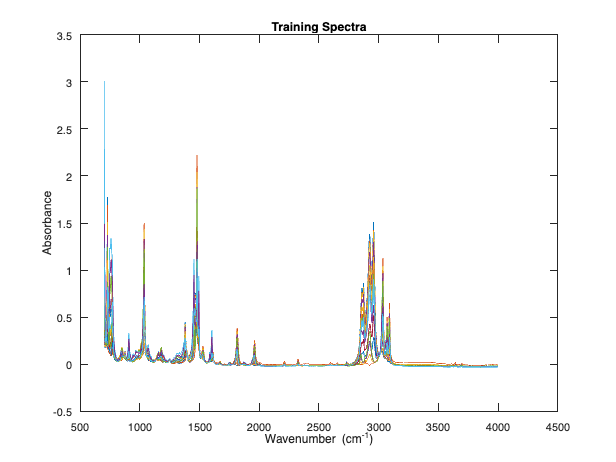

plot(Wavenumbers,A_train)
xlabel(WavenumberLabel)
ylabel('Absorbance')
title('Training Spectra')

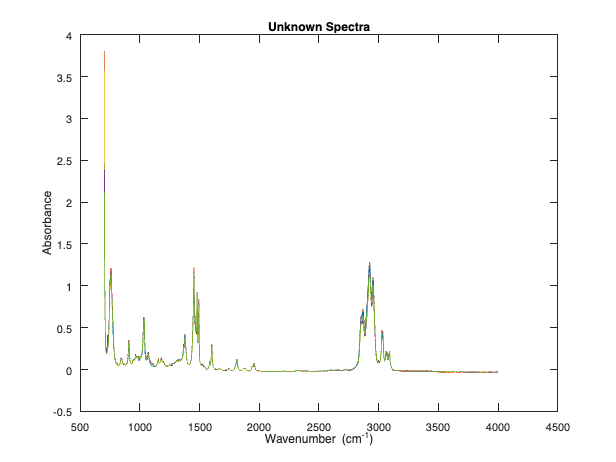

plot(Wavenumbers,A_unknown)
xlabel(WavenumberLabel)
ylabel('Absorbance')
title('Unknown Spectra')

## Root Mean Square Error (RMSE)

The root mean square error of the prediction $C_\textrm{pcr}$ is $\textrm{RMSEP} = \sqrt{\textrm{mean}\left((C_\textrm{pcr}-C_\textrm{validation}).^2\right)}$.  The RMSE algorithm is encapsulated in function `pnnl_rmse`.  Using `vecnorm` is theoretically equivalent, but is better than computing the square and square root with respect to very large or very small numbers.

The columns correspond to the RMSEP of the compnents benzene, polystyrene, and gasolene.

RMSEP_pcr = pnnl_rmse(C_pcr, C_validation) %#ok<*NASGU> 

RMSEP_pcr =     5.1766    2.7318    6.2906


## Calibration Predictions

### Training

You can run a predictor method against the training data.

C_pcr_train = pnnl_pcr(A_train, C_train, A_train, 3);
RMSEC = pnnl_rmse(C_pcr_train, C_train)

RMSEC =     4.6738    2.3109    5.9859


### Cross-validation

You can cross-validate by running a predictor method against the training data.  For each of the rows in the training set, leave one row out, and use that row as the unknown data.  The `pnnl_cross_validation` function encapsulates this, 

where method is a function handle, 

or

or

and the variable input argument `varargin` is the number of principal components for PCR or the number of latent variables for PLS.

For example

C_pcr_cross_validation = pnnl_cross_validation(@pnnl_pcr, A_train, C_train, 3);
RMSECV = pnnl_rmse(C_pcr_cross_validation, C_train)

RMSECV =     5.9206    2.8541    7.4667


## Plot the concentration results

Plot the results of $C_\textrm{validation}$ against $C_\textrm{pcr}$ using a scatter plot

figure
plot(C_validation,C_pcr,'.','MarkerSize',35);

Save the color order of the constituents to coordinate the colors of the training and cross-validation data.

colorOrder = get(gca,'ColorOrder');

Hold the axis and plot the training and cross-validation sets.

hold on

Plot training prediction with `o` marker.

plot(C_train,C_pcr_train,'o','MarkerSize',10,'LineWidth',1)

Plot cross-validation concentrations with `+` marker.

plot(C_train,C_pcr_cross_validation,'+','MarkerSize',10,'LineWidth',1)

Draw a 1-1 line.

line(C_train,C_train,'Color','k');

Reset the color order so the training and cross-validation sets have the same colors for their constituents.

n = size(C_validation,2);
set(gca,'ColorOrder',colorOrder(1:n,:));

Create a legend and make the axis square, so you can see that the training line is 45 degrees.

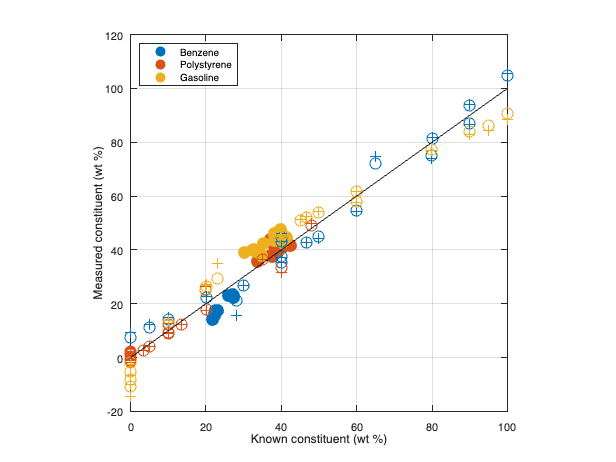

legend(ConstituentNames{:},'Location','northwest')
xlabel('Known constituent (wt %)')
ylabel('Measured constituent (wt %)')
axis square
grid on
box on

Unknown prediction is displayed as a solid dot.  Training predicition is displayed as an open circle.  Cross-validation prediction is displayed as a plus sign.

## Functions that load napalm data, predict, and plot

The following functions encapsulate the steps in the previous sections for each of the methods.  They load the napalm data, predict and plot the concentration matrices, and display the RMSE values.

### Plotting

If you call them with no output arguments, then the plots and displays are shown.  If you input a vector to PCR and PLS, then they are run for the number of principal components or latent variables, respectively.

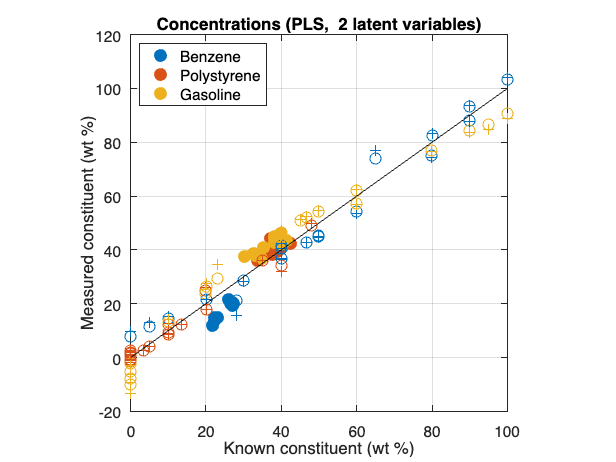

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  2 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC        4.5616        2.2064        5.8133
                    RMSECV        5.8788        2.7588        7.2286
                     RMSEP        7.5077          3.04        5.0846
--------------------------------------------------------------------


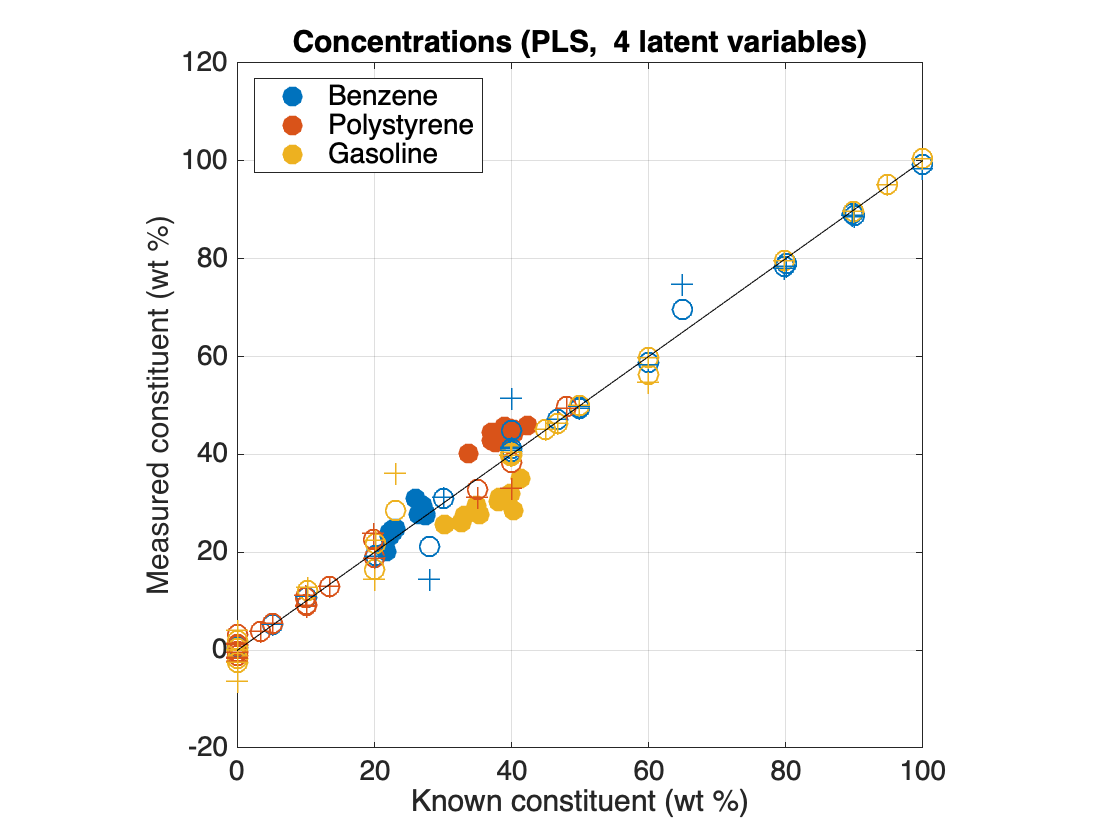

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  4 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC        2.2574        1.3926        1.9696
                    RMSECV        4.6479        2.4087        3.9235
                     RMSEP        2.0484        5.4414         7.344
--------------------------------------------------------------------


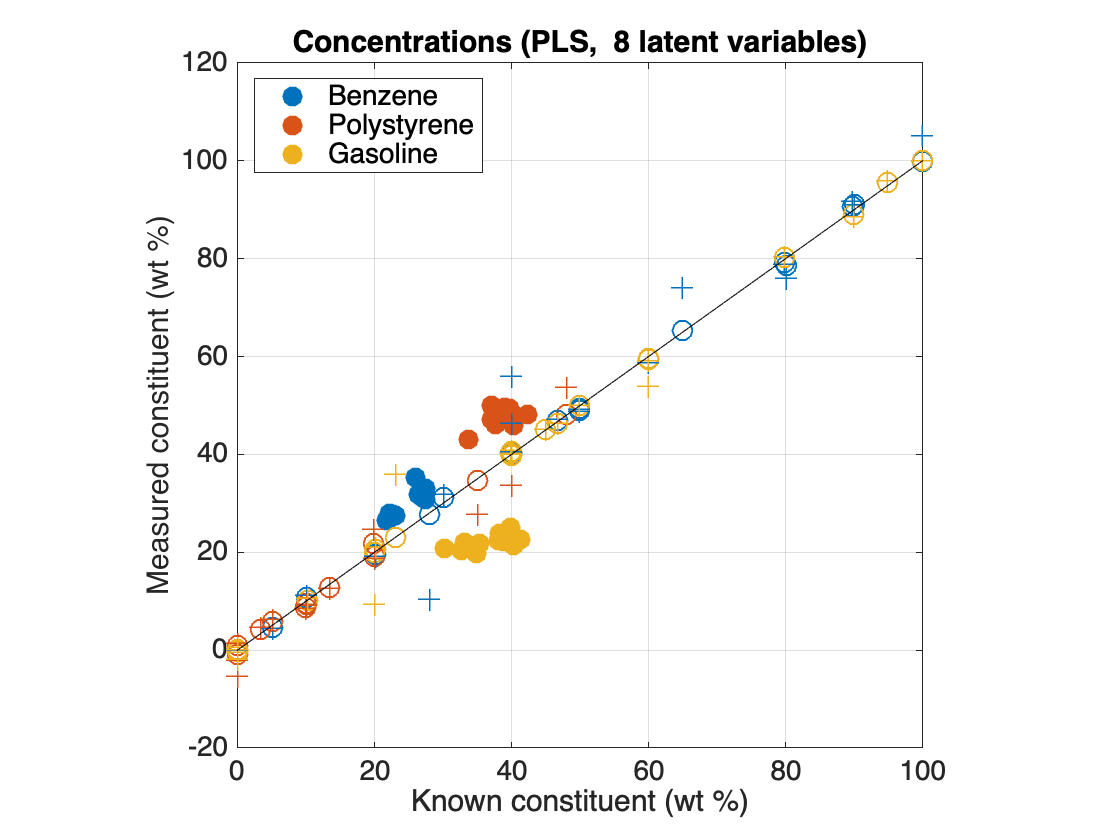

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  8 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC       0.68442       0.71824       0.41195
                    RMSECV        6.1219        3.1259        4.0761
                     RMSEP        5.4028         9.227        14.919
--------------------------------------------------------------------


meanCentered = true;
pnnl_napalm_pls([2 4 8], meanCentered);

### Output Data

The computed data are returned if you call the functions with output arguments, and the plot and display are suppressed.

## Optimal number of principal components for PCR with the napalm data

Compute PCR for 1 through 18 principal components and plot RMSEP for them.

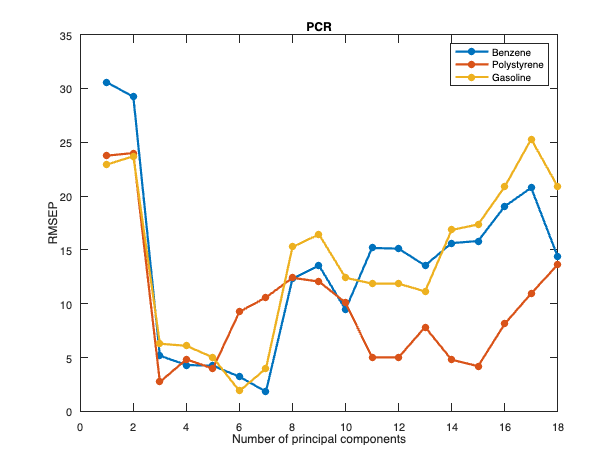

nPrincipalComponents = 1:18;
[C_pcr, RMSEP_pcr] = pnnl_napalm_pcr(nPrincipalComponents);
plot(nPrincipalComponents, RMSEP_pcr,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of principal components')
ylabel('RMSEP')
title('PCR')
legend(ConstituentNames{:})

It looks like 3 is the knee in the curve for all constituents, with 7 being better for benzene and 6 being better for gasolene.  It may be best to use 3 principal components across the board, but visualize 3, 7, and 6 to see what they look like.

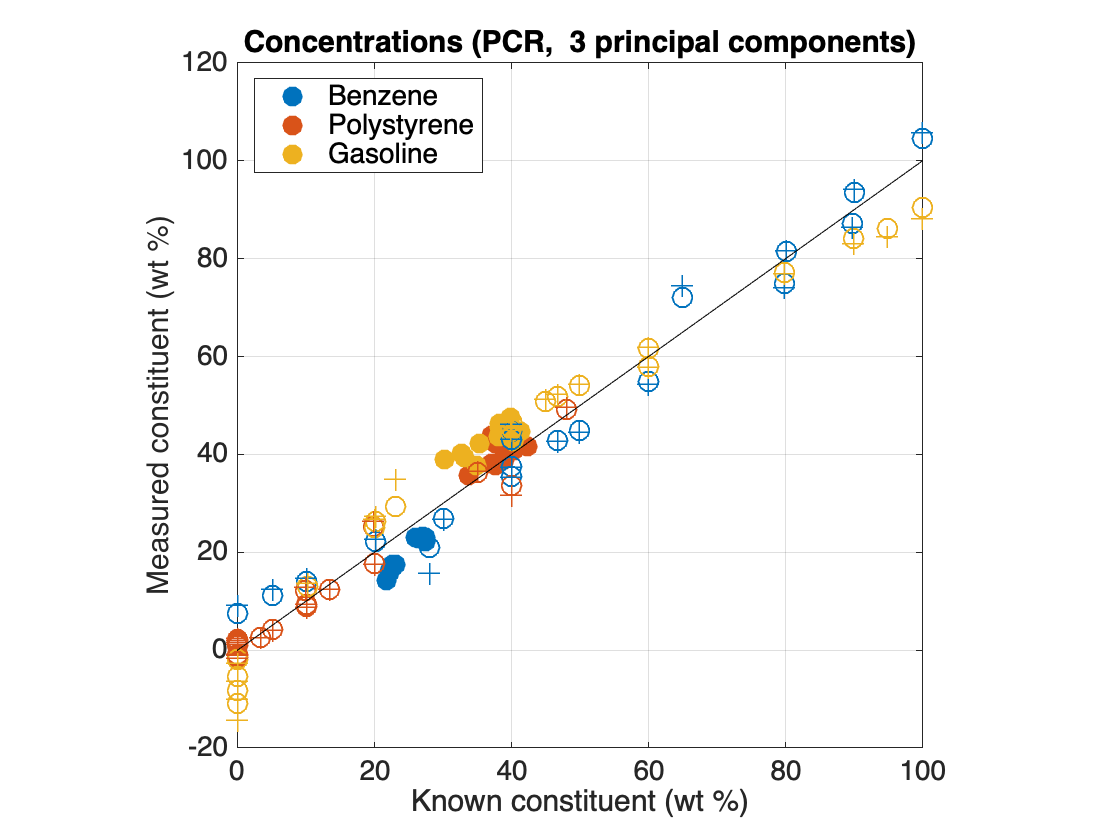

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
------------------------------------------------------------------------
  PCR,  3 principal components       Benzene   Polystyrene      Gasoline
                         RMSEC        4.6738        2.3109        5.9859
                        RMSECV        5.9206        2.8541        7.4667
                         RMSEP        5.1766        2.7318        6.2906
------------------------------------------------------------------------


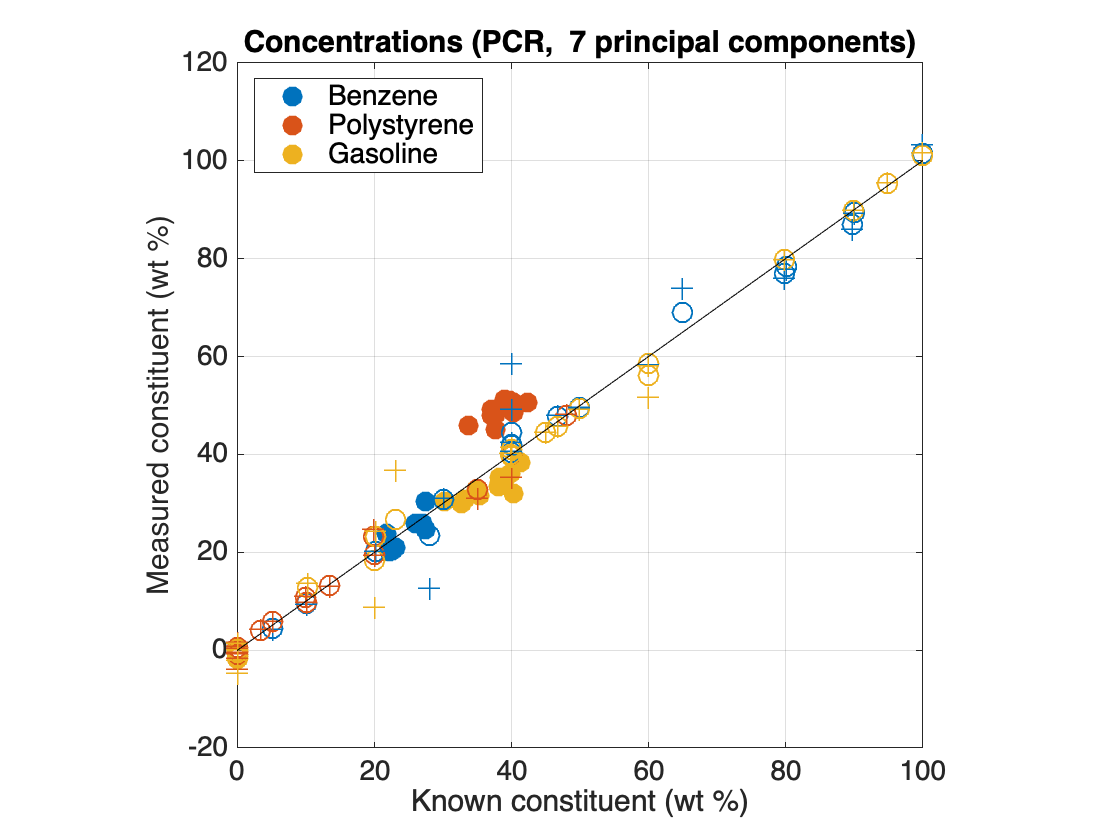

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
------------------------------------------------------------------------
  PCR,  7 principal components       Benzene   Polystyrene      Gasoline
                         RMSEC        2.1605        1.0254        1.7212
                        RMSECV        6.3531        2.0739        4.7611
                         RMSEP        1.8345        10.584        3.9805
------------------------------------------------------------------------


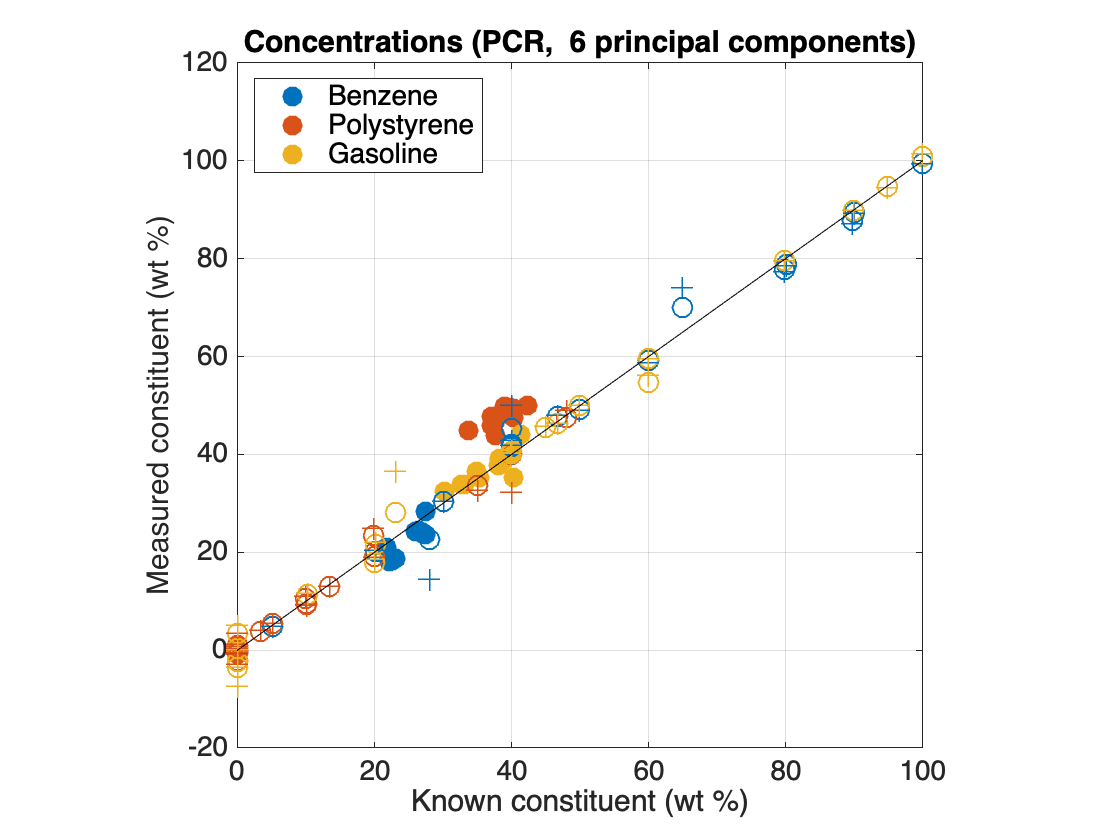

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
------------------------------------------------------------------------
  PCR,  6 principal components       Benzene   Polystyrene      Gasoline
                         RMSEC         2.262        1.1177        2.1723
                        RMSECV         4.499        2.4207        3.8803
                         RMSEP        3.2226        9.2569         1.898
------------------------------------------------------------------------


nPrincipalComponents = [3 7 6]; 
pnnl_napalm_pcr(nPrincipalComponents);

## Optimal number of latent variables for PLS with the napalm data

Compute PLS for 1 through 18 latent variables and plot RMSEP for them.

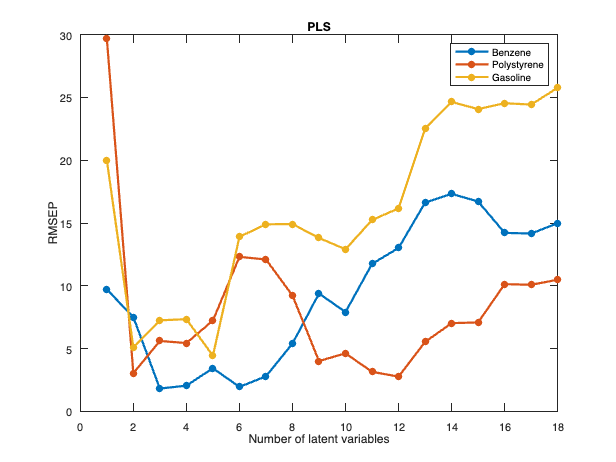

nLatentVariables = 1:18;
meanCentered = true;
[C_pls, RMSEP_pls] = pnnl_napalm_pls(nLatentVariables, meanCentered);
plot(nLatentVariables, RMSEP_pls,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of latent variables')
ylabel('RMSEP')
title('PLS')
legend(ConstituentNames{:})

It looks like the knee in the curve for benzene is 3 latent variables, and 2 for polystyrene and gasolene.  Plot them to see what they look like.

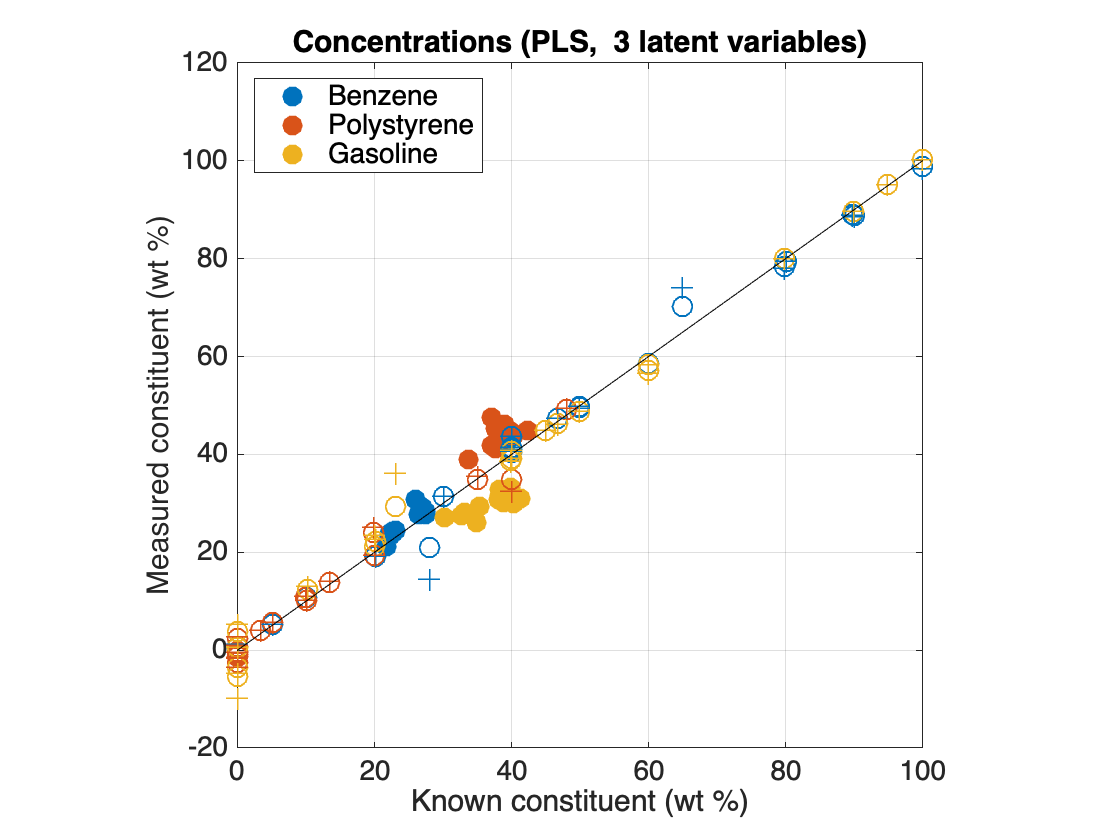

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  3 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC        2.2847        1.7662        2.4538
                    RMSECV        3.9022        2.4136        4.2785
                     RMSEP        1.8185        5.6092        7.2521
--------------------------------------------------------------------


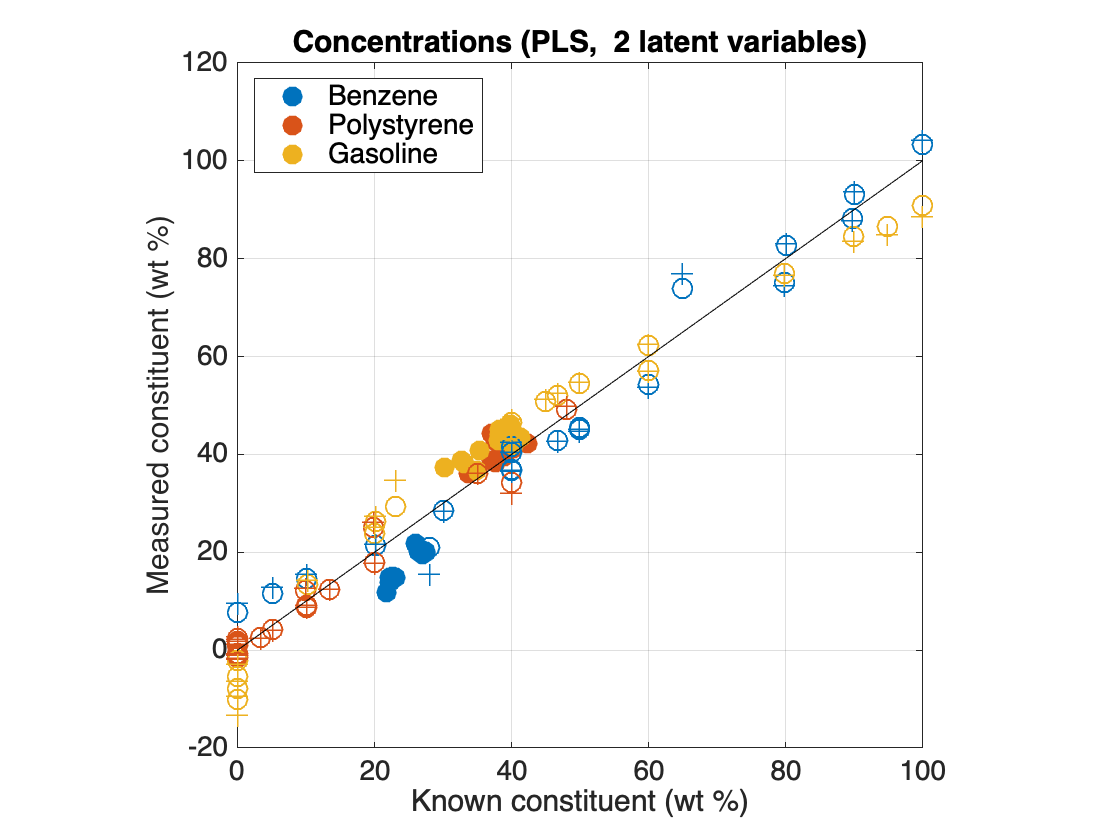

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  2 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC        4.5616        2.2064        5.8133
                    RMSECV        5.8788        2.7588        7.2286
                     RMSEP        7.5077          3.04        5.0846
--------------------------------------------------------------------


nLatentVariables = [3 2];
meanCentered = true;
pnnl_napalm_pls(nLatentVariables,meanCentered);

# Single Constituent Analysis

## Single-Constituent Analysis Function

Loop over one constituent at a time for a range of number of principal components for PCR or latent variables for PLS

where

or

## PCR single-constituent analysis

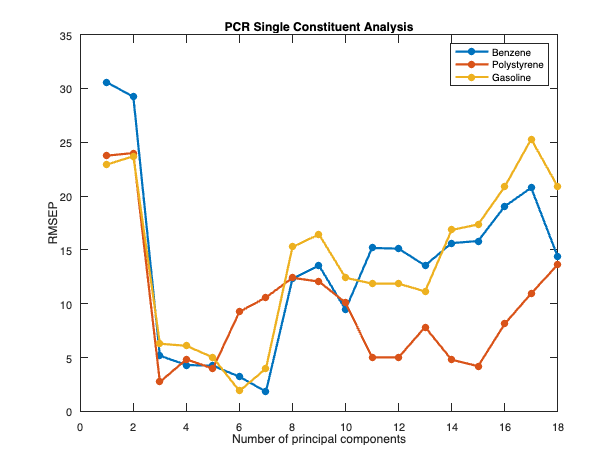

nPrincipalComponents = 1:18;
[C_pcr_single,RMSEP_pcr_single,C_pcr_train,RMSEC_pcr_single,C_pcr_cross_validation,RMSECV_pcr_single] = pnnl_single_constituent_analysis(@pnnl_pcr,A_train,C_train,A_unknown,C_validation,nPrincipalComponents);

figure
plot(nPrincipalComponents, RMSEP_pcr_single,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of principal components')
ylabel('RMSEP')
title('PCR Single Constituent Analysis')
legend(ConstituentNames{:})

RMSEP_pcr_single

RMSEP_pcr_single =    30.5754   23.7626   22.9313
   29.2247   23.9980   23.7022
    5.1766    2.7318    6.2906
    4.3080    4.8366    6.0915
    4.2423    3.9788    5.0158
    3.2226    9.2569    1.8980
    1.8345   10.5841    3.9805
   12.3262   12.4126   15.2784
   13.5406   12.0606   16.4394
    9.4668   10.0999   12.4205


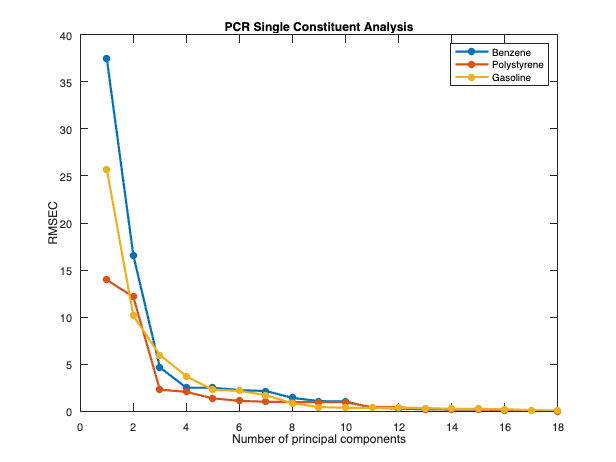

figure
plot(nPrincipalComponents, RMSEC_pcr_single,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of principal components')
ylabel('RMSEC')
title('PCR Single Constituent Analysis')
legend(ConstituentNames{:})

RMSEC_pcr_single

RMSEC_pcr_single =    37.4380   13.9664   25.7064
   16.5607   12.1515   10.1419
    4.6738    2.3109    5.9859
    2.5151    2.0734    3.7362
    2.5081    1.3847    2.3022
    2.2620    1.1177    2.1723
    2.1605    1.0254    1.7212
    1.4392    0.9970    0.8625
    1.0894    0.9765    0.4660
    1.0551    0.9680    0.3838


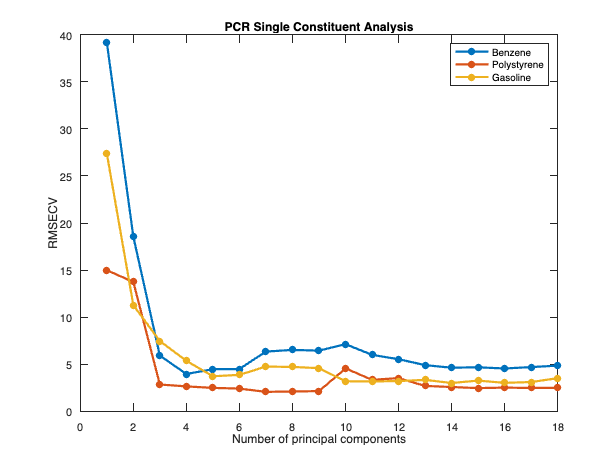

figure
plot(nPrincipalComponents, RMSECV_pcr_single,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of principal components')
ylabel('RMSECV')
title('PCR Single Constituent Analysis')
legend(ConstituentNames{:})

RMSECV_pcr_single

RMSECV_pcr_single =    39.1802   14.9894   27.3785
   18.5368   13.7424   11.2736
    5.9206    2.8541    7.4667
    3.9695    2.6545    5.3672
    4.4832    2.4979    3.7294
    4.4990    2.4207    3.8803
    6.3531    2.0739    4.7611
    6.5274    2.1158    4.7216
    6.4514    2.1532    4.5899
    7.1394    4.5678    3.2023


## PLS single-constituent analysis (PLS1)

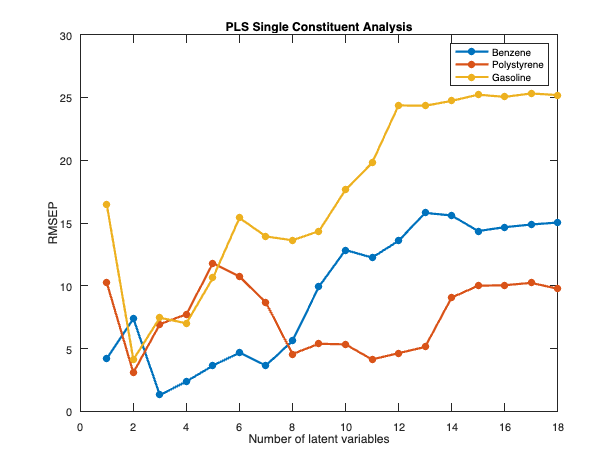

nLatentVariables = 1:18;
meanCentered = true;
[C_pls_single,RMSEP_pls_single,C_pls_train,RMSEC_pls_single,C_pls_cross_validation,RMSECV_pls_single] = pnnl_single_constituent_analysis(@pnnl_pls,A_train,C_train,A_unknown,C_validation,nLatentVariables,meanCentered);

figure
plot(nLatentVariables, RMSEP_pls_single,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of latent variables')
ylabel('RMSEP')
title('PLS Single Constituent Analysis')
legend(ConstituentNames{:})

RMSEP_pls_single

RMSEP_pls_single =     4.2080   10.2402   16.4432
    7.3905    3.0818    4.1248
    1.3096    6.9468    7.4590
    2.3801    7.7360    7.0172
    3.6426   11.8017   10.6290
    4.6758   10.7408   15.4054
    3.6591    8.6560   13.9297
    5.6087    4.5684   13.6261
    9.9386    5.3861   14.3570
   12.8500    5.3368   17.6503


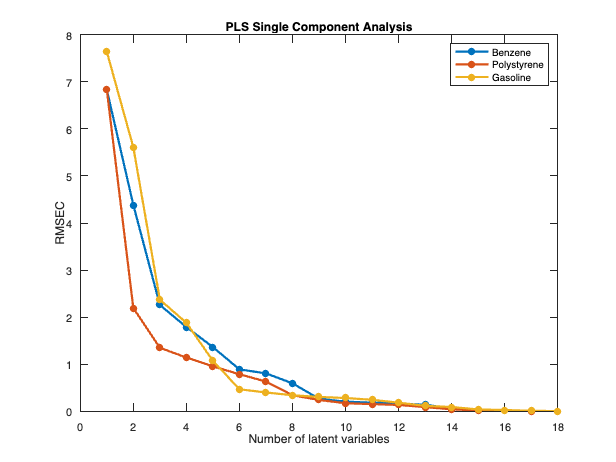


figure
plot(nLatentVariables, RMSEC_pls_single,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of latent variables')
ylabel('RMSEC')
title('PLS Single Component Analysis')
legend(ConstituentNames{:})

RMSEC_pls_single

RMSEC_pls_single =     6.8289    6.8274    7.6372
    4.3821    2.1913    5.6067
    2.2597    1.3507    2.3716
    1.7915    1.1442    1.8808
    1.3650    0.9566    1.0751
    0.8919    0.7892    0.4700
    0.8077    0.6338    0.4020
    0.5967    0.3433    0.3430
    0.2679    0.2428    0.3068
    0.2072    0.1740    0.2846


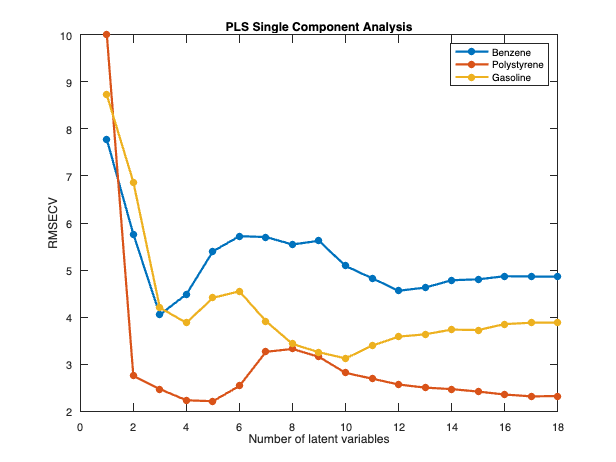

figure
plot(nLatentVariables, RMSECV_pls_single,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of latent variables')
ylabel('RMSECV')
title('PLS Single Component Analysis')
legend(ConstituentNames{:})

RMSECV_pls_single

RMSECV_pls_single =     7.7757    9.9992    8.7190
    5.7622    2.7529    6.8702
    4.0534    2.4738    4.2017
    4.4860    2.2357    3.8805
    5.3984    2.2166    4.4115
    5.7206    2.5403    4.5507
    5.7025    3.2655    3.9151
    5.5449    3.3264    3.4324
    5.6225    3.1571    3.2554
    5.0880    2.8177    3.1258


# Principal Components and Principal Component Scores

## Scores definition

The scores are the left-singular vectors multiplied by the singular values of the absorbance matrix. The economy-size singular value decomposition is


$$$$%
\underset{p\times m}{A} = %
\underset{p\times p}{U}\cdot\underset{p\times p}{\Sigma}\cdot\underset{p\times m}{V^\textrm{T}}%
$$$$


where $U$ and $V$ have orthonormal columns, $\Sigma = \textrm{diag}(\sigma_1,\, \sigma_2,\, \ldots \sigma_p)$, and $\sigma_1 \geq \sigma_2 \geq \cdots \sigma_p \geq 0$.

It can be written as a sum of rank-one outer products


$$$$%
\underset{p\times m}{A} = %
\sigma_1\underset{p\times 1}{U(\,:\,,1)}\underset{1\times m}{V(\,:\,,1)^\textrm{T}} +%
\sigma_2\underset{p\times 1}{U(\,:\,,2)}\underset{1\times m}{V(\,:\,,2)^\textrm{T}} +%
\cdots +%
\sigma_p\underset{p\times 1}{U(\,:\,,p)}\underset{1\times m}{V(\,:\,,p)^\textrm{T}}.%
$$$$


where $\sigma_iU(\,:\,,i)$ is called the score of the $i$ th principal component $V(\,:\,,i)$ ([Cleve Moler, "Professor SVD"](https://www.mathworks.com/company/newsletters/articles/professor-svd.html)).

In matrix form, this is written as

$$$%
\textrm{Scores} = U\Sigma
$$$.

## Singular Value Decomposition

Function `pnnl_rectifiedSVD` returns the economy-size singular value decomposition, where the maximum magnitude element of each column of V is positive, which is the convention for principal components.  The singular value decomposition is unique up to the signs of the columns of U and V, like `1*2*1 == -1*2*-1`.  Rectified singular value decompositions are unique, which makes it convenient to compare one score to another.

[U,S,V] = pnnl_rectifiedSVD(A_train);

## Principal Components

The principal components are the right singular vectors in the columns of matrix $V$. 

Plot the first four principal components.

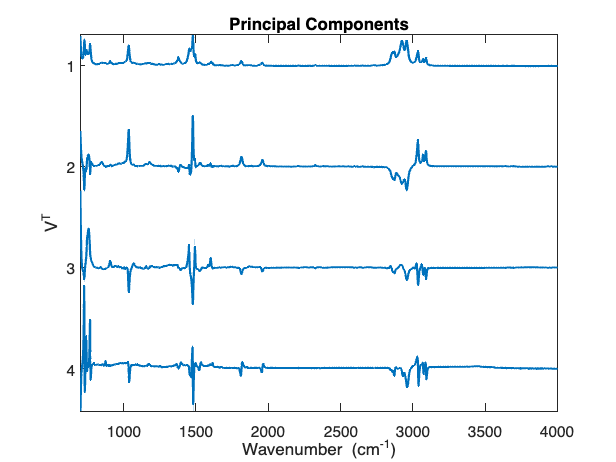

figure
pnnl_strip_plot(Wavenumbers,V(:,1:4)',...
    'Principal Components',...
    WavenumberLabel,'V^T')

## Principal Compent Scores

The scores are the left singular vectors multplied by the singular values.

Scores = U*S;

Plot the scores of one principal component against the other.

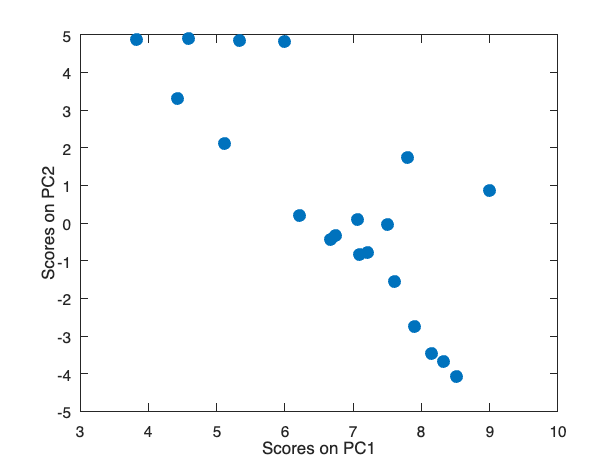

fontSize = 14;
plot(Scores(:,1),Scores(:,2),'.','MarkerSize',35);
xlabel('Scores on PC1');
ylabel('Scores on PC2');
set(gca,'FontSize',fontSize);
box on

## Plot scores with labels

The scores only rely on an absorbance matrix, without having to know the actual concentrations.  If you also know the concentrations, then you can use that information to label the scores.  Function `pnnl_plot_scores` computes and plots the scores as in the previous section, and also uses information in the known concentrations to label the scores plot.

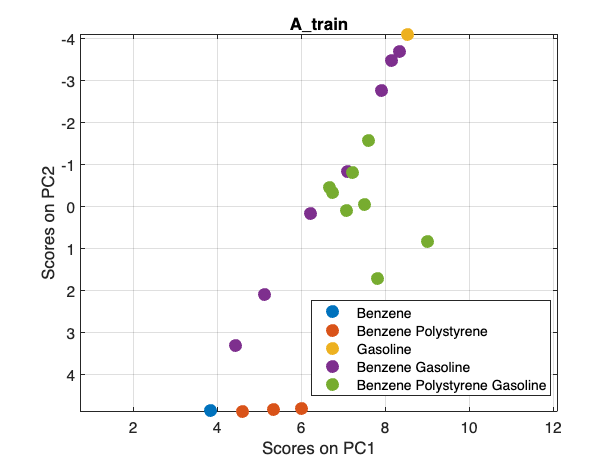

pnnl_plot_scores(A_train, C_train, 1, 2, ConstituentNames)

## Display concentration percentages of training set

If you input an additional parameter to `pnnl_plot_scores`, then it will also display the concentration percentages as (%benzene, %polystyrene, %gasoline), which may be useful to zoom in and explore the linear relationship between the scores.

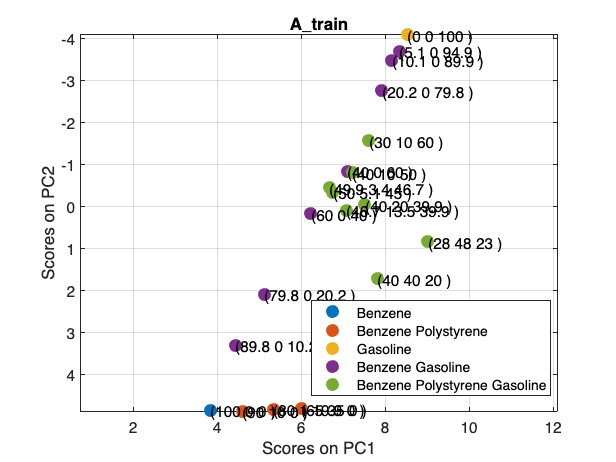

displayConcentrations = true;
pnnl_plot_scores(A_train, C_train, 1, 2, ConstituentNames, displayConcentrations)

## Display concentration percentages of unknown set

If you input an additional parameter to `pnnl_plot_scores`, then it will also display the concentration percentages as (%benzene, %polystyrene, %gasoline), which may be useful to zoom in and explore the linear relationship between the scores.

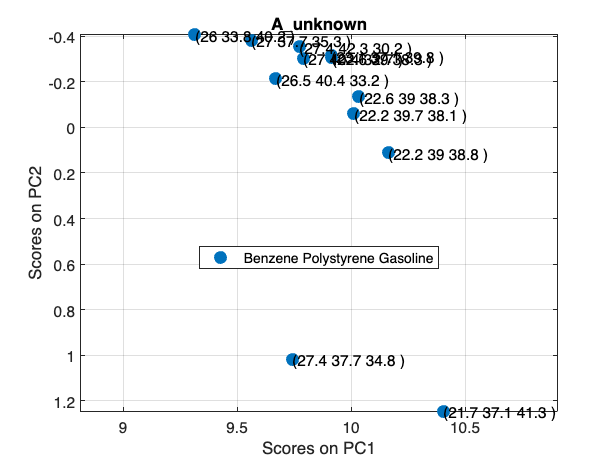

displayConcentrations = true;
pnnl_plot_scores(A_unknown, C_validation, 1, 2, ConstituentNames, displayConcentrations)

## Display all combinations of scores

Function `pnnl_napalm_plot_scores` loads the napalm data set and loops over all combinations of principal components.

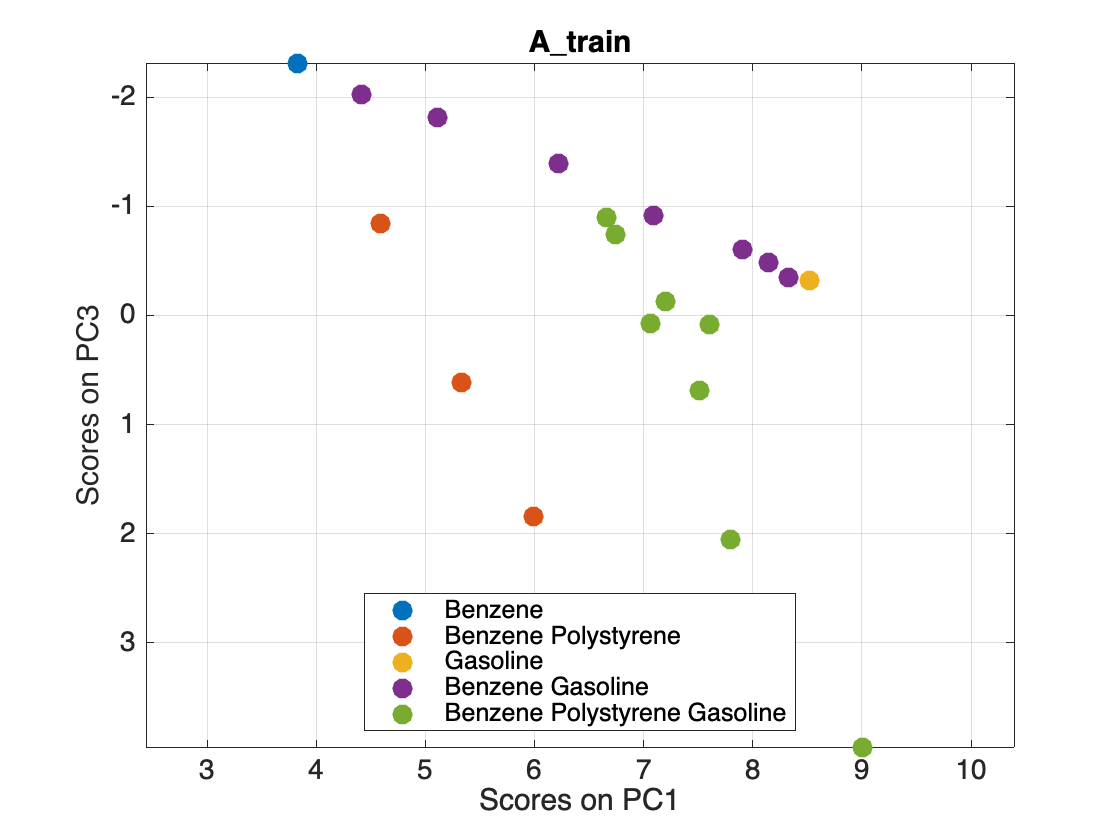

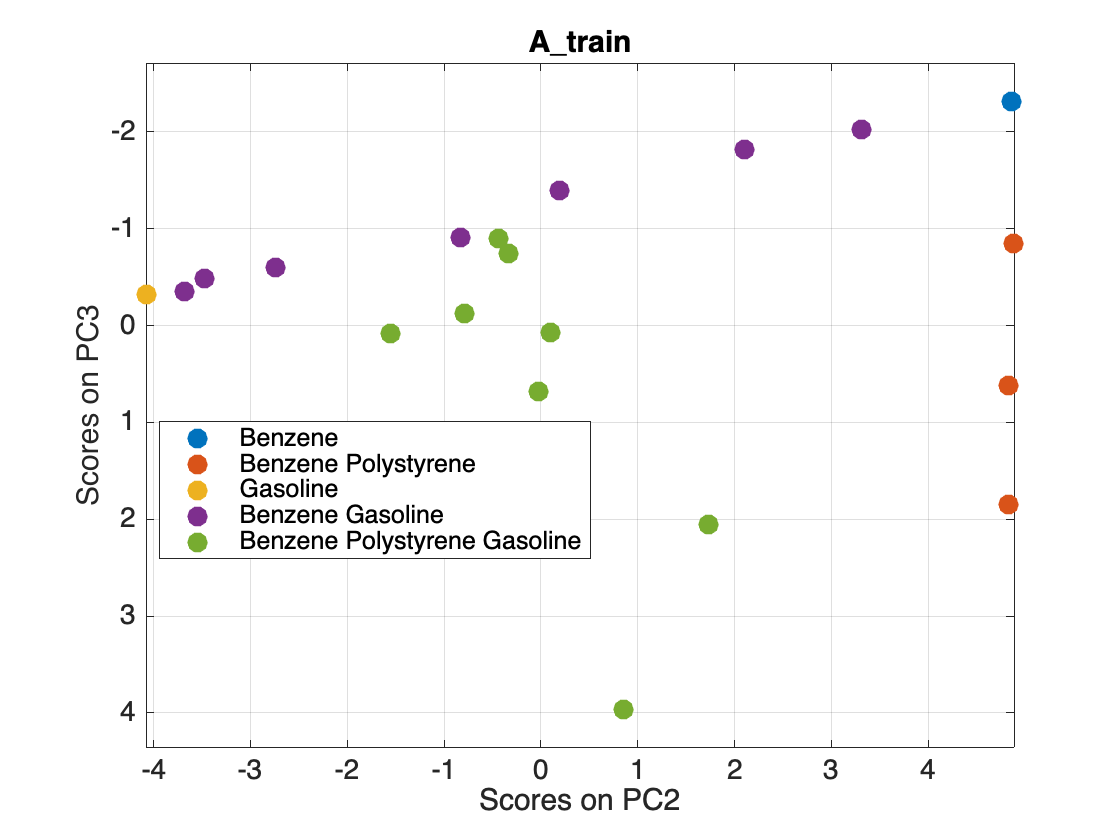

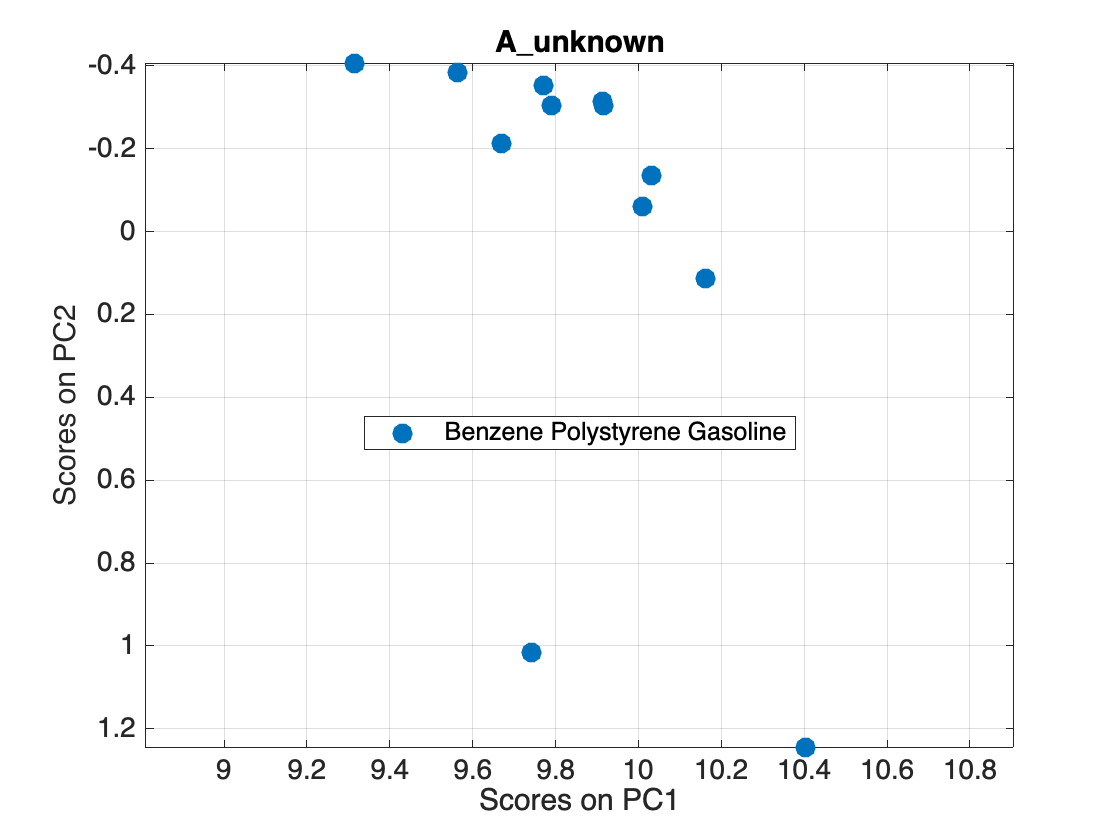

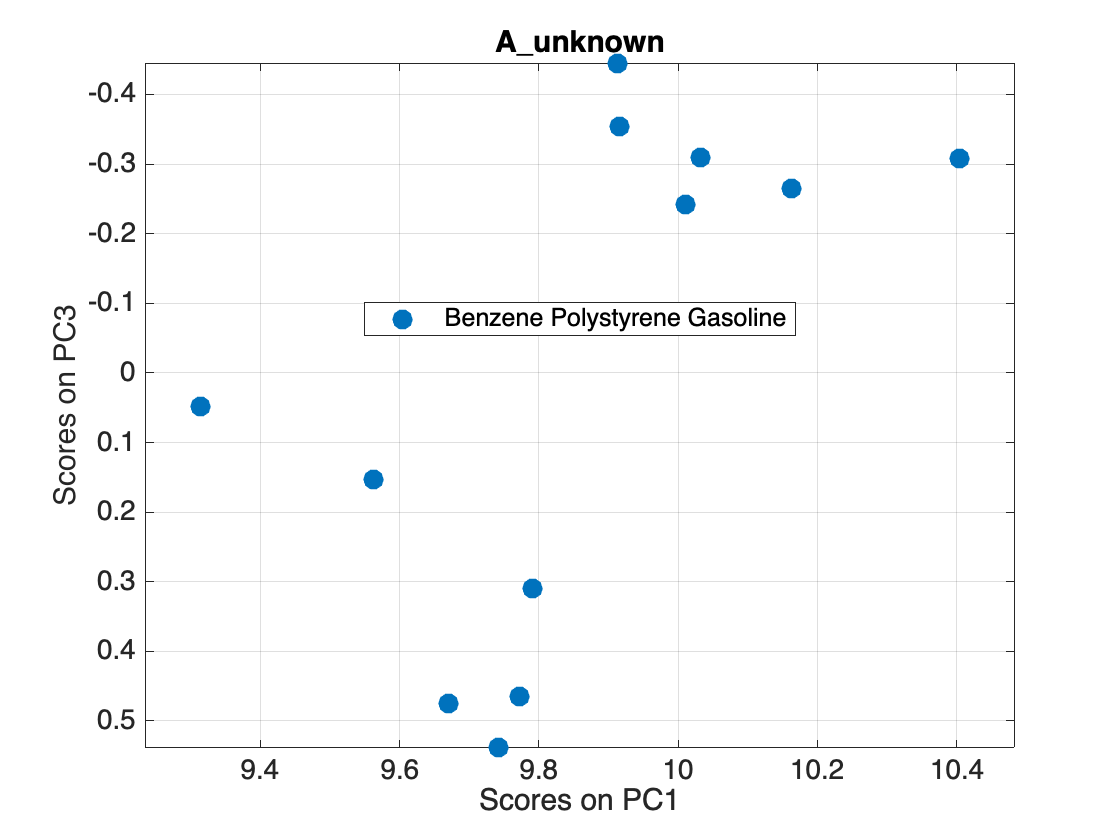

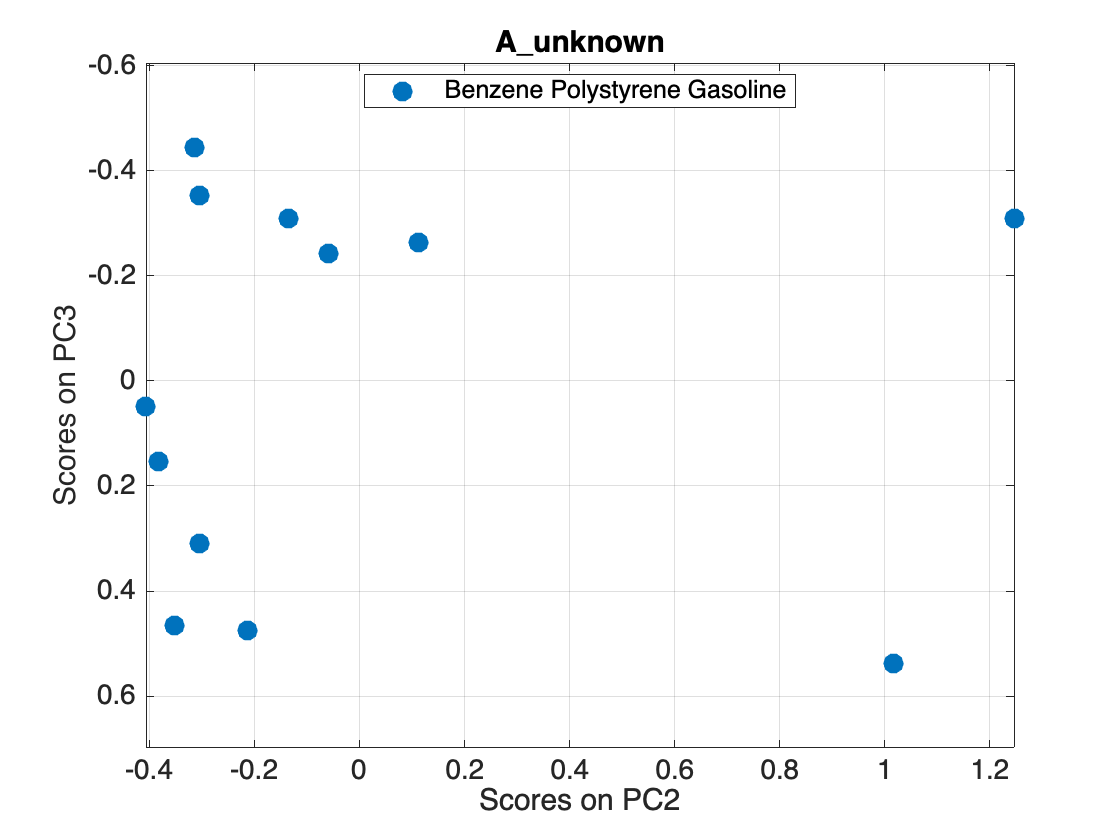

pnnl_napalm_plot_scores

# Spectra

## Measured spectra

The `pnnl_napalm_plot_spectra` function plots the napalm spectra meaasured in $A_\textrm{train}$ and $A_\textrm{unknown}$.

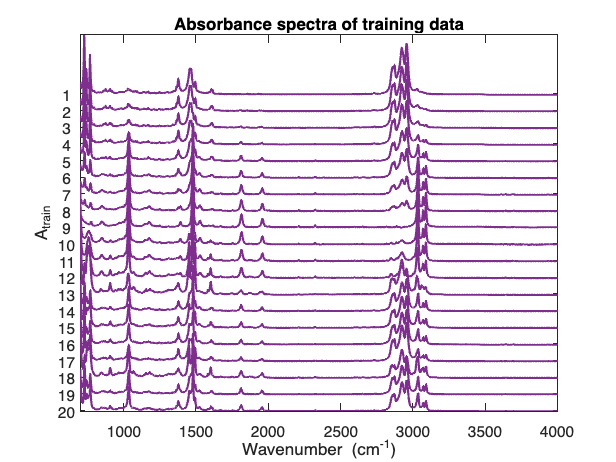

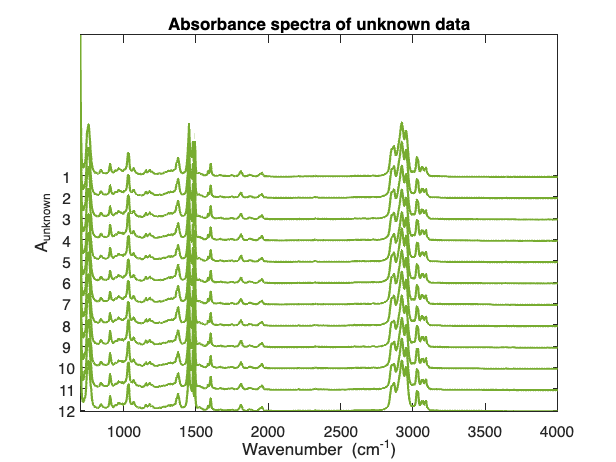

pnnl_napalm_plot_spectra

## CLS K vs Pure Spectra

Classical least squares computes $C_\textrm{cls}$ that minimizes $||CK-A||_2$, where $CK=A$ is the Beer's law relationship between concentration $C$, extinction coefficient $K$ and absorbtion $A$.  An estimation of the extinction coefficient matrix $K_\textrm{cls}$ is computed as a byproduct of the CLS method.  

You can see in the following plots that the rows of $K_\textrm{cls}$ match the spectra of the pure constituents.

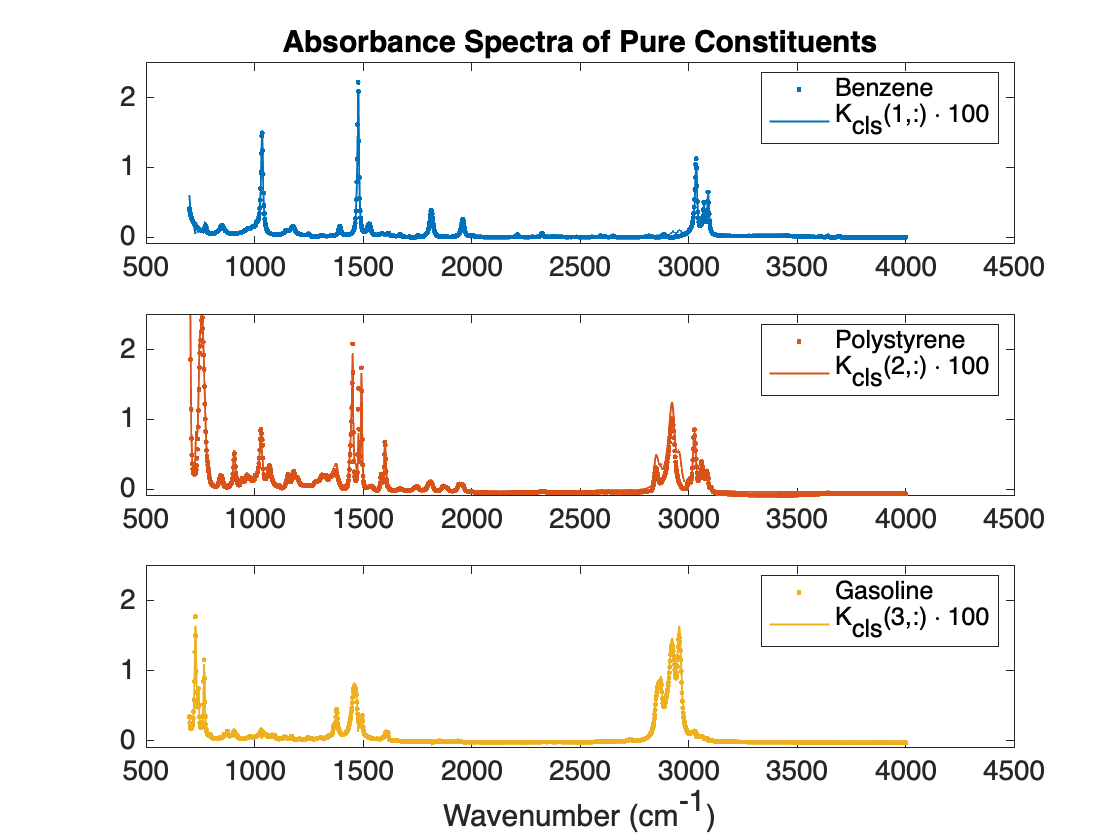

[C_cls, B_cls, K_cls] = pnnl_cls(A_train, C_train, A_unknown);
pnnl_napalm_plot_pure_spectra_vs_K_cls

# Ternary plot

You can see the overlap between $C_\textrm{train}$ and $C_\textrm{validation}$ concentraions by plotting them in a ternary plot.

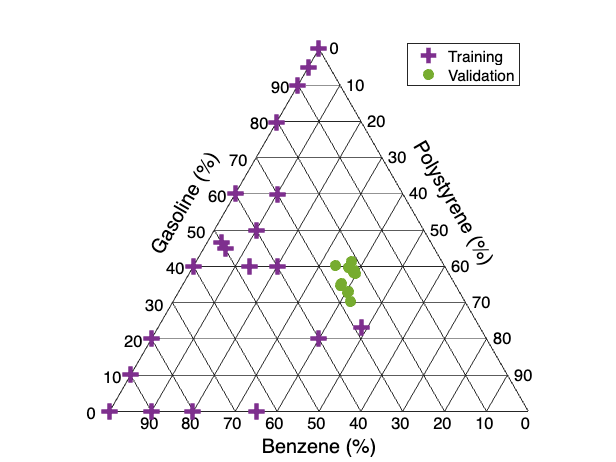

pnnl_napalm_plot_concentration_ternary

# Glossary

## Methods

- Classical Least Squares (CLS)

- Principal Component Regression (PCR)

- Partial Least Squares (PLS)

## Numbers

- $m$ is the number of measured wavenumbers.  In the napalm data, $m=1713$.

- $n$ is the number of constituents.  In the napalm data, $n=3$ for constituents benzene, polystyrene, and gasoline.

- $p$ is the number of compounds.  In the napalm data, $p_\textrm{train}=20$ for the training compounds, and $p_\textrm{unknown}=12$for the unknown compounds.

- $r$ is the number of principal components in PCR, and the number of latent variables in PLS.

## Matrices

- $A$ is a matrix of absorbance spectra

- $C$ is a matrix of concentrations

- $K$ is a matrix of normalized extinction coefficients

## Specific Matrices

- $A_\textrm{train}$ is the measured absorbance matrix from the training solutions.

- $A_\textrm{unknown}$ is the measured absorbance matrix from the solution with unknown concentrations

- $C_\textrm{train}$ is the matrix of known concentrations (measured into the solution)

- $C_\textrm{validation}$ is the matrix of concentrations of the unknown solution derived by an independent means

- $C_\textrm{cls}$, $C_\textrm{pcr}$, $C_\textrm{pls}$ is the concentration matrix of the unknown solution computed using CLS, PCR, PLS respectively

- $K_\textrm{cls}$, $K_\textrm{pcr}$, $K_\textrm{pls}$ is the matrix of normalized extinction coefficients computed using CLS, PCR, PLS respectively

## Root Mean Square Error

- $\textrm{RMSE} = \textrm{pnnl\_rmse}(C_\textrm{computed},C_\textrm{known}) = \sqrt{\textrm{mean}\left((C_\textrm{computed}-C_\textrm{known}).^2\right)}$. Root mean square error between a computed value and a known value. 

- $\textrm{RMSEP} = \textrm{pnnl\_rmse}(C_\textrm{predicted}, C_\textrm{validation})$. RMSEP is the prediction error measured on real cases and compared to reference values.

- $\textrm{RMSEC} = \textrm{pnnl\_rmse}(C_\textrm{predicted from train}, C_\textrm{train})$. RMSEC is the calibration error.  $C_\textrm{predicted from train}$ is computed by using $A_\textrm{train}$ as the unknown.

- $\textrm{RMSECV} = \textrm{pnnl\_rmse}(C_\textrm{cross validation}, C_\textrm{train})$.   RMSECV is the cross-validation error. For each of the rows in the training set $C_\textrm{train}$ and $A_\textrm{train}$, leave one row out, and use that row as the unknown data in the predictor.  Store the result in $C_\textrm{cross-validation}$.  Then compute the RMSE between $C_\textrm{cross validation}$ and $C_\textrm{train}$.

# Disclaimer

This material was prepared as an account of work sponsored by an agency of the United States Government. Neither the United States Government nor the United States Department of Energy, nor Battelle, nor any of their employees, nor any jurisdiction or organization that has cooperated in the development of these materials, makes any warranty, express or implied, or assumes any legal liability or responsibility for the accuracy, completeness, or usefulness or any information, apparatus, product, software, or process disclosed, or represents that its use would not infringe privately owned rights.

Reference herein to any specific commercial product, process, or service by trade name, trademark, manufacturer, or otherwise does not necessarily constitute or imply its endorsement, recommendation, or favoring by the United States Government or any agency thereof, or Battelle Memorial Institute. The views and opinions of authors expressed herein do not necessarily state or reflect those of the United States Government or any agency thereof.

PACIFIC NORTHWEST NATIONAL LABORATORY

operated by

BATTELLE

for the

UNITED STATES DEPARTMENT OF ENERGY

under Contract DE-AC05-76RL01830